# Ex 1.11

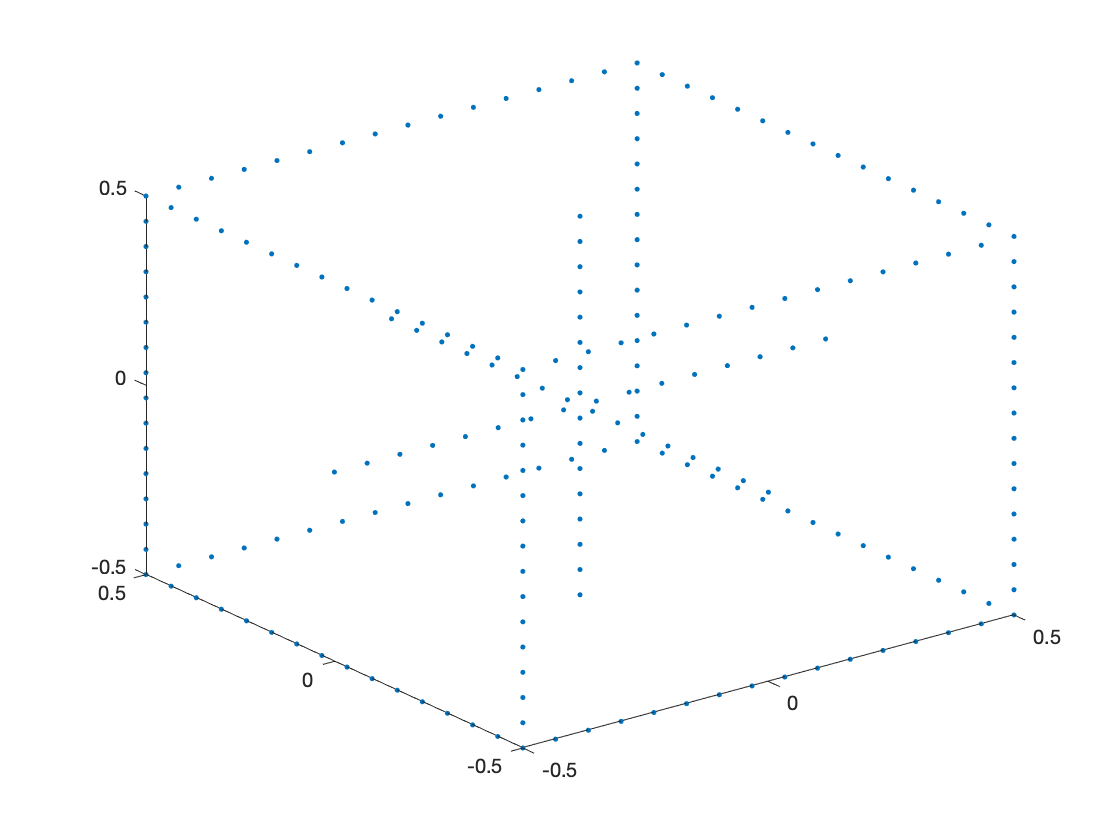

n = 16;
[X,Y,Z] = ndgrid(-0.5:1/(n-1):0.5, -0.5, 0.5);
Q = [X(:), Y(:), Z(:)];

[X,Y,Z] = ndgrid(-0.5, -0.5, -0.5:1/(n-1):0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(-0.5:1/(n-1):0.5, -0.5, -0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(0.5, -0.5, -0.5:1/(n-1):0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(0.5, -0.5:1/(n-1):0.5, 0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(0.5, 0.5, -0.5:1/(n-1):0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(0.5, -0.5:1/(n-1):0.5, -0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(-0.5:1/(n-1):0.5, 0.5, 0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(-0.5, 0.5, -0.5:1/(n-1):0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(-0.5:1/(n-1):0.5, 0.5, -0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(-0.5, -0.5:1/(n-1):0.5, -0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(-0.5, -0.5:1/(n-1):0.5, 0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(-0.5:1/(n-1):0.5, 0, 0);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(0, 0, -0.5:1/(n-1):0.5);
Q = [Q ; [X(:), Y(:), Z(:)]];

[X,Y,Z] = ndgrid(0, -0.5:1/(n-1):0.5, 0);
Q = [Q ; [X(:), Y(:), Z(:)]];

plot3(Q(:,1), Q(:,2), Q(:,3), '.')

## Ex 1.12

K = [1 0 0; 0 1 0; 0 0 1];
R = [1 0 0; 0 1 0; 0 0 1];
t = [0; 0; 4];
p = K * [R t];
Q_1 = [Q ones(size(Q,1), 1)];
Ph = p * Q_1';

Ph =    -0.5000   -0.4333   -0.3667   -0.3000   -0.2333   -0.1667   -0.1000   -0.0333    0.0333    0.1000    0.1667    0.2333    0.3000    0.3667    0.4333    0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.4333   -0.3667   -0.3000   -0.2333   -0.1667   -0.1000   -0.0333    0.0333    0.1000    0.1667    0.2333    0.3000    0.3667    0.4333    0.5000    0.5000    0.5000
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -

projection = Ph(1:2,:)./Ph(3,:)

position2D =    -0.1111   -0.0963   -0.0815   -0.0667   -0.0519   -0.0370   -0.0222   -0.0074    0.0074    0.0222    0.0370    0.0519    0.0667    0.0815    0.0963    0.1111   -0.1429   -0.1402   -0.1376   -0.1351   -0.1327   -0.1304   -0.1282   -0.1261   -0.1240   -0.1220   -0.1200   -0.1181   -0.1163   -0.1145   -0.1128   -0.1111   -0.1429   -0.1238   -0.1048   -0.0857   -0.0667   -0.0476   -0.0286   -0.0095    0.0095    0.0286    0.0476    0.0667    0.0857    0.1048    0.1238    0.1429    0.1429    0.1402
   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1429   -0.1402   -0.1376   -0.1351   -0.1327   -0.1304   -0.1282   -0.1261   -0.1240   -0.1220   -0.1200   -0.1181   -0.1163   -0.1145   -0.1128   -0.1111   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.

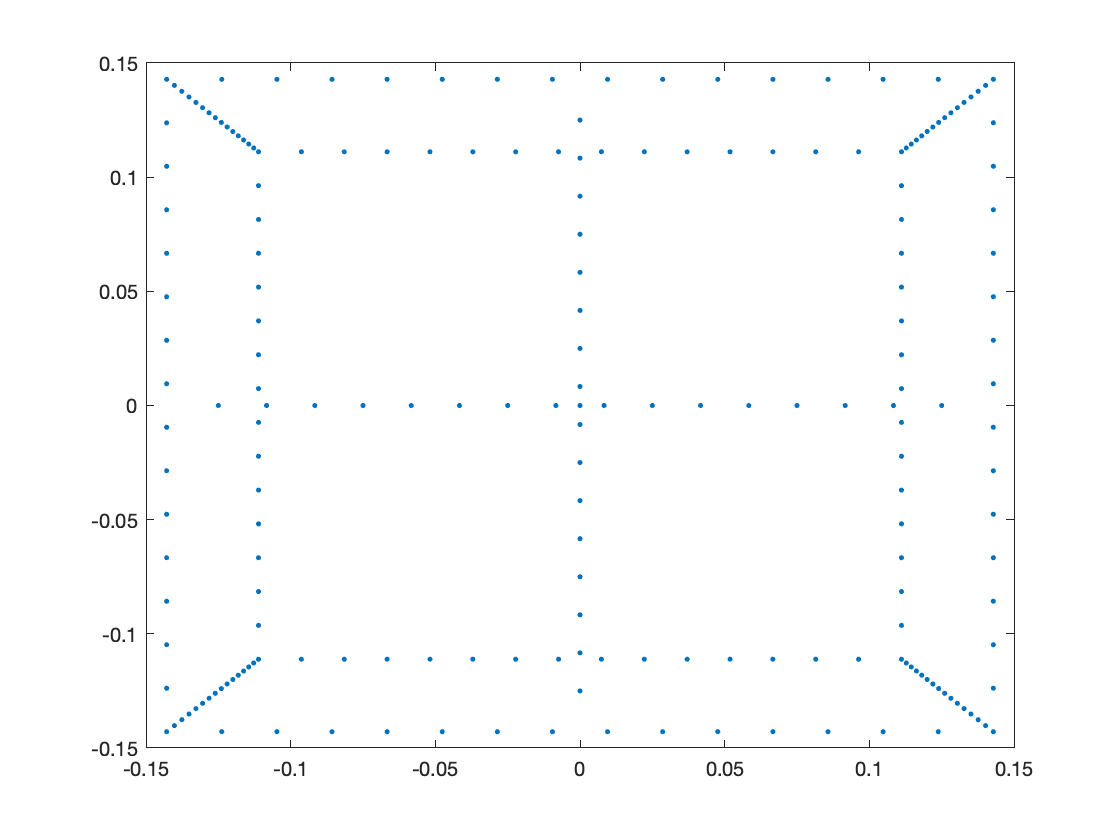

position2D =    -0.1111   -0.0963   -0.0815   -0.0667   -0.0519   -0.0370   -0.0222   -0.0074    0.0074    0.0222    0.0370    0.0519    0.0667    0.0815    0.0963    0.1111   -0.1429   -0.1402   -0.1376   -0.1351   -0.1327   -0.1304   -0.1282   -0.1261   -0.1240   -0.1220   -0.1200   -0.1181   -0.1163   -0.1145   -0.1128   -0.1111   -0.1429   -0.1238   -0.1048   -0.0857   -0.0667   -0.0476   -0.0286   -0.0095    0.0095    0.0286    0.0476    0.0667    0.0857    0.1048    0.1238    0.1429    0.1429    0.1402
   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1429   -0.1402   -0.1376   -0.1351   -0.1327   -0.1304   -0.1282   -0.1261   -0.1240   -0.1220   -0.1200   -0.1181   -0.1163   -0.1145   -0.1128   -0.1111   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.1429   -0.

plot(projection(1,:), projection(2,:), '.')

## Ex 1.13

K = [1 0 0; 0 1 0; 0 0 1];
R = [0.5 0 sqrt(3)/2; 0 1 0; -sqrt(3)/2 0 0.5];
t = [0; 0; 4];
p = K * [R t];
Q_1 = [Q ones(size(Q,1), 1)];
Ph = p * Q_1';
projection = Ph(1:2,:)./Ph(3,:)

position2D =     0.0391    0.0468    0.0547    0.0628    0.0711    0.0796    0.0883    0.0973    0.1065    0.1160    0.1258    0.1358    0.1461    0.1567    0.1677    0.1789   -0.1633   -0.1483   -0.1335   -0.1190   -0.1047   -0.0907   -0.0768   -0.0631   -0.0497   -0.0364   -0.0234   -0.0105    0.0021    0.0146    0.0269    0.0391   -0.1633   -0.1575   -0.1515   -0.1454   -0.1391   -0.1326   -0.1259   -0.1190   -0.1119   -0.1046   -0.0970   -0.0892   -0.0811   -0.0727   -0.0641   -0.0552   -0.0552   -0.0374
   -0.1068   -0.1081   -0.1095   -0.1109   -0.1123   -0.1138   -0.1153   -0.1169   -0.1185   -0.1201   -0.1218   -0.1235   -0.1253   -0.1271   -0.1290   -0.1310   -0.1195   -0.1186   -0.1177   -0.1167   -0.1158   -0.1150   -0.1141   -0.1132   -0.1124   -0.1115   -0.1107   -0.1099   -0.1091   -0.1083   -0.1075   -0.1068   -0.1195   -0.1212   -0.1229   -0.1247   -0.1265   -0.1284   -0.1303   -0.1323   -0.1344   -0.1365   -0.1387   -0.1409   -0.1433   -0.1457   -0.1482   -0.1507   -0.

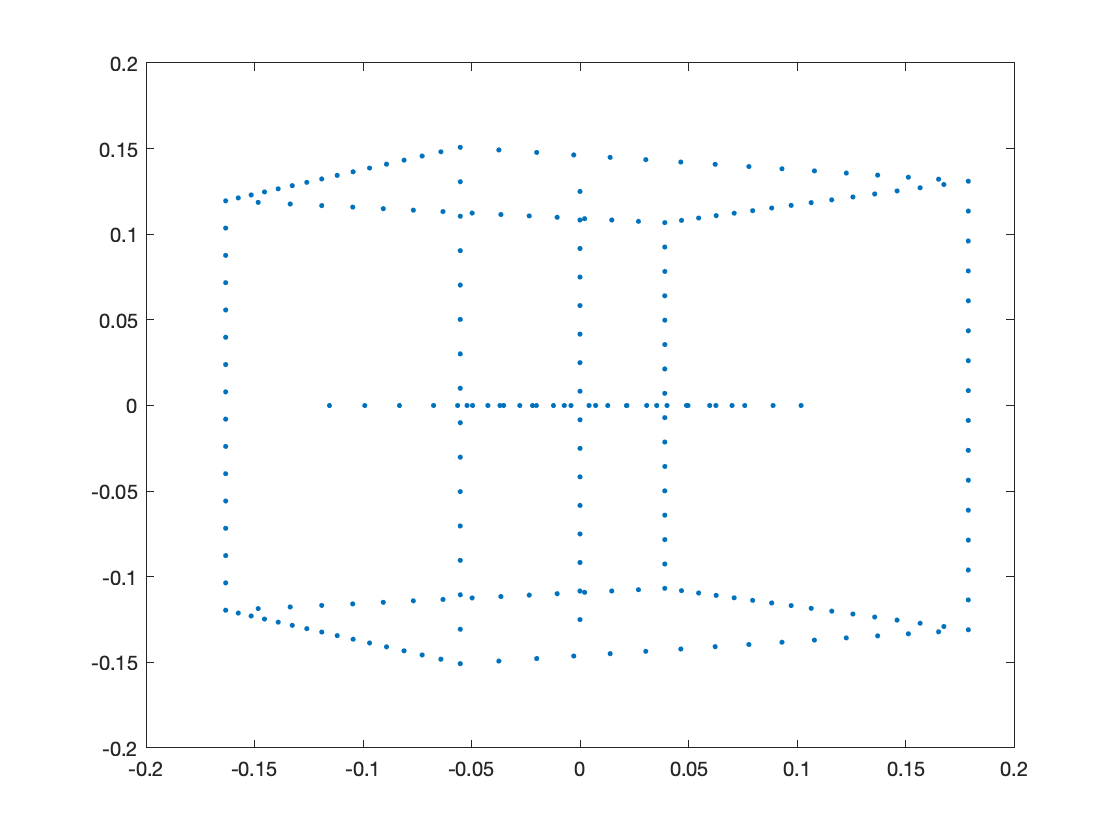

position2D =     0.0391    0.0468    0.0547    0.0628    0.0711    0.0796    0.0883    0.0973    0.1065    0.1160    0.1258    0.1358    0.1461    0.1567    0.1677    0.1789   -0.1633   -0.1483   -0.1335   -0.1190   -0.1047   -0.0907   -0.0768   -0.0631   -0.0497   -0.0364   -0.0234   -0.0105    0.0021    0.0146    0.0269    0.0391   -0.1633   -0.1575   -0.1515   -0.1454   -0.1391   -0.1326   -0.1259   -0.1190   -0.1119   -0.1046   -0.0970   -0.0892   -0.0811   -0.0727   -0.0641   -0.0552   -0.0552   -0.0374
   -0.1068   -0.1081   -0.1095   -0.1109   -0.1123   -0.1138   -0.1153   -0.1169   -0.1185   -0.1201   -0.1218   -0.1235   -0.1253   -0.1271   -0.1290   -0.1310   -0.1195   -0.1186   -0.1177   -0.1167   -0.1158   -0.1150   -0.1141   -0.1132   -0.1124   -0.1115   -0.1107   -0.1099   -0.1091   -0.1083   -0.1075   -0.1068   -0.1195   -0.1212   -0.1229   -0.1247   -0.1265   -0.1284   -0.1303   -0.1323   -0.1344   -0.1365   -0.1387   -0.1409   -0.1433   -0.1457   -0.1482   -0.1507   -0.

plot(projection(1,:), projection(2,:), '.')

## Ex 2.1

K = [600 0 400; 0 600 400; 0 0 1];
R = [1 0 0; 0 1 0; 0 0 1];
t = [0; 0.2; 1.5];
p = K * [R t];
Q_1 = [Q ones(size(Q,1), 1)];
Ph = p * Q_1';
projection = Ph(1:2,:)./Ph(3,:)

projection =   250.0000  270.0000  290.0000  310.0000  330.0000  350.0000  370.0000  390.0000  410.0000  430.0000  450.0000  470.0000  490.0000  510.0000  530.0000  550.0000  100.0000  118.7500  135.2941  150.0000  163.1579  175.0000  185.7143  195.4545  204.3478  212.5000  220.0000  226.9231  233.3333  239.2857  244.8276  250.0000  100.0000  140.0000  180.0000  220.0000  260.0000  300.0000  340.0000  380.0000  420.0000  460.0000  500.0000  540.0000  580.0000  620.0000  660.0000  700.0000  700.0000  681.2500
  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  310.0000  220.0000  231.2500  241.1765  250.0000  257.8947  265.0000  271.4286  277.2727  282.6087  287.5000  292.0000  296.1538  300.0000  303.5714  306.8966  310.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.0000  220.

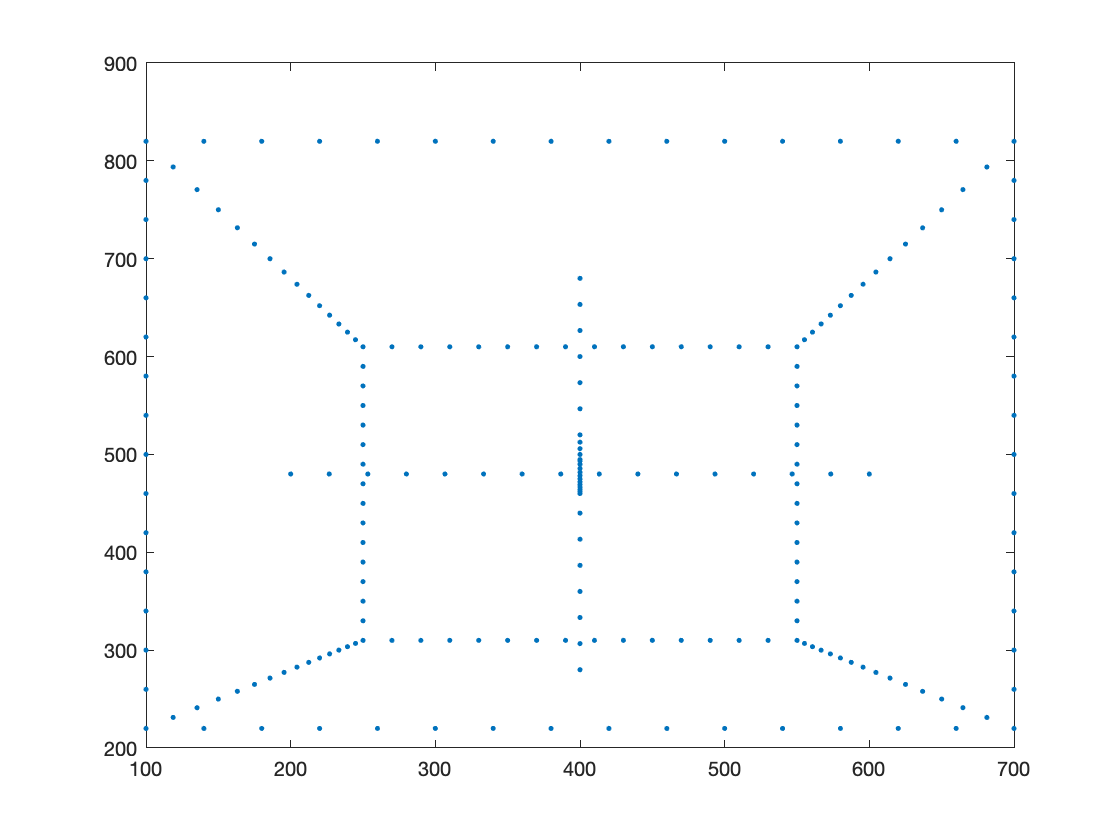

plot(projection(1,:), projection(2,:), '.')


%P1 projection
Q_p1 = [-0.5 -0.5 -0.5]

Q_p1 =    -0.5000   -0.5000   -0.5000


Q_1 = [Q_p1 ones(size(Q_p1,1), 1)];
Ph = p * Q_1';
projection = Ph(1:2,:)./Ph(3,:)

projection =    100
   220


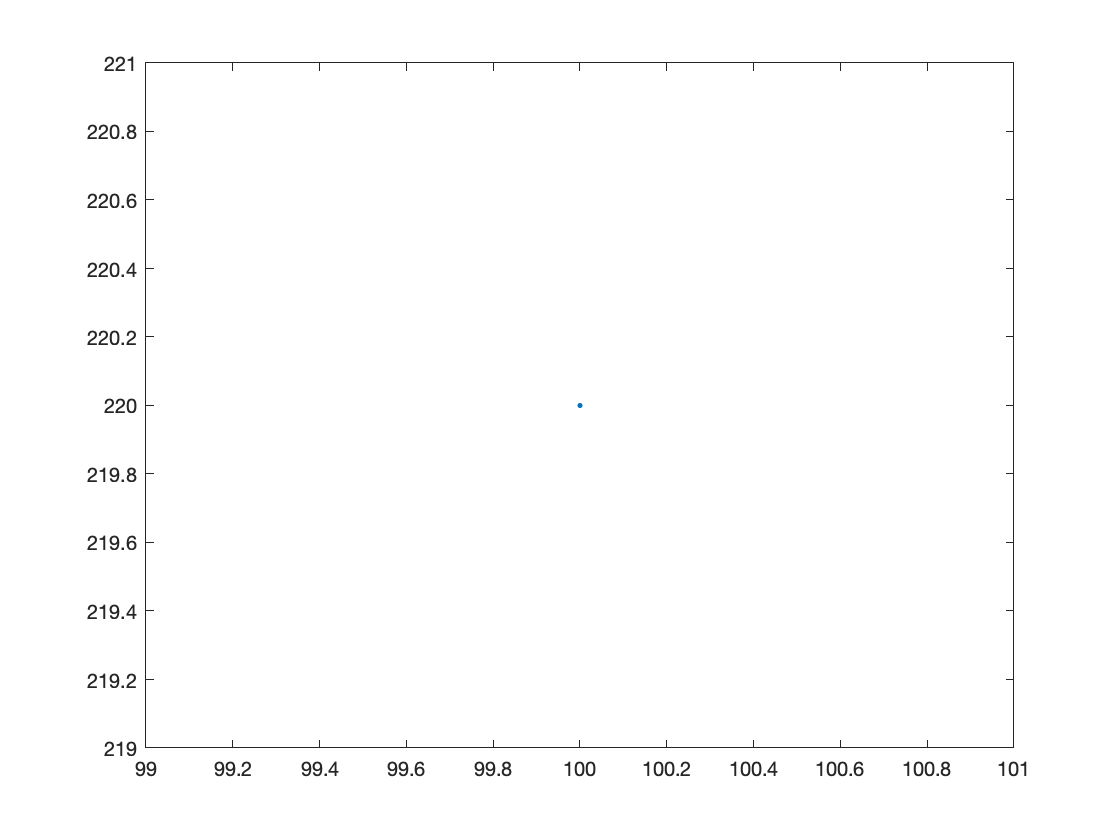

plot(projection(1,:), projection(2,:), '.')

## Ex 2.2

K = [600 0 400; 0 600 400; 0 0 1];
R = [1 0 0; 0 1 0; 0 0 1];
t = [0; 0.2; 1.5];
Q_p1 = [-0.5 -0.5 -0.5]

Q_p1 =    -0.5000   -0.5000   -0.5000


Q_1 = [Q_p1 ones(size(Q_p1,1), 1)];

k3 = -5.1806 * 10^(-8);
k5 = 1.4192 * 10^(-15);
k7 = 0;

%%
p = [R t] * Q_1';
p = p(1:2) ./ p(3);
dist_p = p * (1 + k3*(norm(p)).^2 + k5 * (norm(p)).^4 + k7 * (norm(p)).^6 )

dist_p =    -0.5000
   -0.3000


q = K * [dist_p; 1]

q =   100.0000
  220.0000
    1.0000



%%
dist_p_1 = p * (1 + -0.2 * norm(p).^2)

dist_p_1 =    -0.4660
   -0.2796


q = K * [dist_p_1;1]

q =   120.4000
  232.2400
    1.0000




% 
Q_1 = [Q' ;ones(1, size(Q,1))]

Q_1 =    -0.5000   -0.4333   -0.3667   -0.3000   -0.2333   -0.1667   -0.1000   -0.0333    0.0333    0.1000    0.1667    0.2333    0.3000    0.3667    0.4333    0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.4333   -0.3667   -0.3000   -0.2333   -0.1667   -0.1000   -0.0333    0.0333    0.1000    0.1667    0.2333    0.3000    0.3667    0.4333    0.5000    0.5000    0.5000
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   

p = [R t] * Q_1;
p = p(1:2,:) ./ p(3,:)

p =    -0.2500   -0.2167   -0.1833   -0.1500   -0.1167   -0.0833   -0.0500   -0.0167    0.0167    0.0500    0.0833    0.1167    0.1500    0.1833    0.2167    0.2500   -0.5000   -0.4688   -0.4412   -0.4167   -0.3947   -0.3750   -0.3571   -0.3409   -0.3261   -0.3125   -0.3000   -0.2885   -0.2778   -0.2679   -0.2586   -0.2500   -0.5000   -0.4333   -0.3667   -0.3000   -0.2333   -0.1667   -0.1000   -0.0333    0.0333    0.1000    0.1667    0.2333    0.3000    0.3667    0.4333    0.5000    0.5000    0.4688
   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.1500   -0.3000   -0.2812   -0.2647   -0.2500   -0.2368   -0.2250   -0.2143   -0.2045   -0.1957   -0.1875   -0.1800   -0.1731   -0.1667   -0.1607   -0.1552   -0.1500   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0

dist_p = p * (1 + -0.2 * norm(p).^2)

dist_p =     1.1490    0.9958    0.8426    0.6894    0.5362    0.3830    0.2298    0.0766   -0.0766   -0.2298   -0.3830   -0.5362   -0.6894   -0.8426   -0.9958   -1.1490    2.2980    2.1544    2.0276    1.9150    1.8142    1.7235    1.6414    1.5668    1.4987    1.4362    1.3788    1.3258    1.2767    1.2311    1.1886    1.1490    2.2980    1.9916    1.6852    1.3788    1.0724    0.7660    0.4596    0.1532   -0.1532   -0.4596   -0.7660   -1.0724   -1.3788   -1.6852   -1.9916   -2.2980   -2.2980   -2.1544
    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    0.6894    1.3788    1.2926    1.2166    1.1490    1.0885    1.0341    0.9849    0.9401    0.8992    0.8617    0.8273    0.7955    0.7660    0.7386    0.7132    0.6894    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788    1.3788

q = K * [dist_p; ones(1, size(dist_p, 2))]

q = 	1.0e+03 *

    1.0894    0.9975    0.9056    0.8136    0.7217    0.6298    0.5379    0.4460    0.3540    0.2621    0.1702    0.0783   -0.0136   -0.1056   -0.1975   -0.2894    1.7788    1.6926    1.6166    1.5490    1.4885    1.4341    1.3849    1.3401    1.2992    1.2617    1.2273    1.1955    1.1660    1.1386    1.1132    1.0894    1.7788    1.5950    1.4111    1.2273    1.0434    0.8596    0.6758    0.4919    0.3081    0.1242   -0.0596   -0.2434   -0.4273   -0.6111   -0.7950   -0.9788   -0.9788   -0.8926
    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    0.8136    1.2273    1.1756    1.1300    1.0894    1.0531    1.0205    0.9909    0.9641    0.9395    0.9170    0.8964    0.8773    0.8596    0.8432    0.8279    0.8136    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273    1.2273   

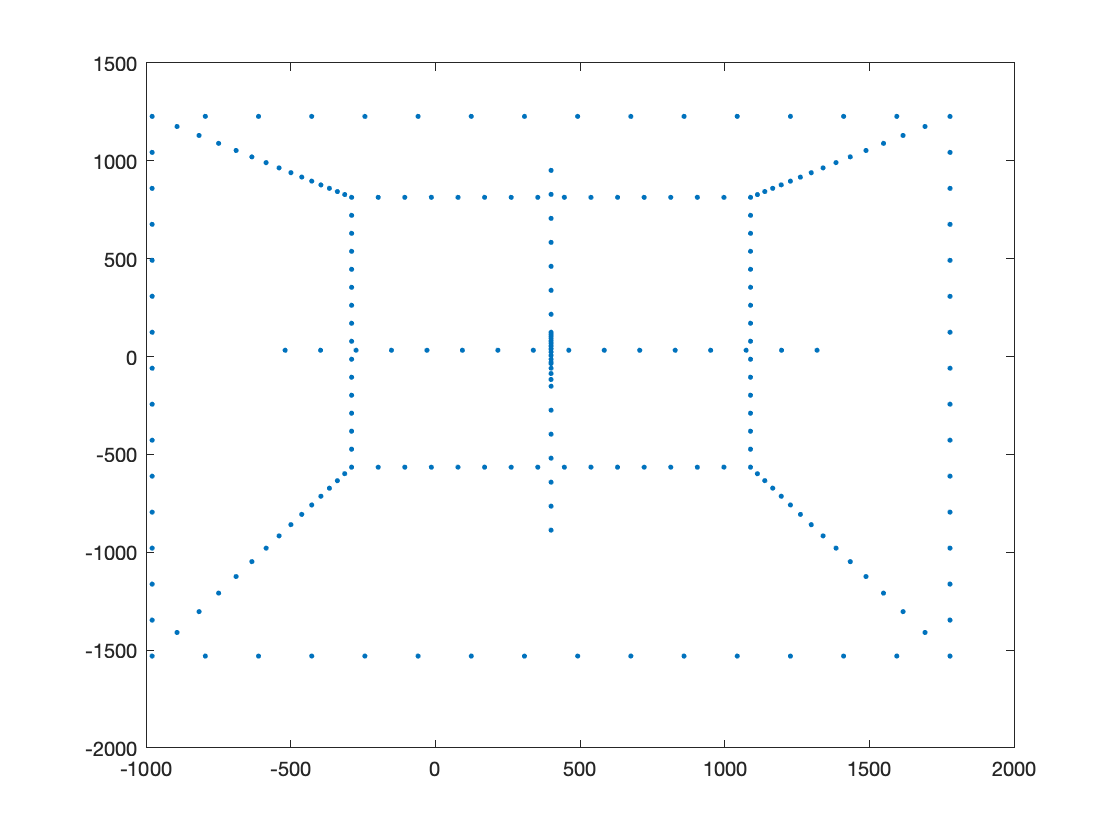

plot(q(1,:), q(2,:), '.')